# CONDITION TOPOPLOTS*

## First retreive Master Data Set

cog_task_list = {'PVT'};
df_long =  dflong('cogtestlist',cog_task_list,'getd2cdf',false);


Getting GPSD during PVT Task. . . . . . . . . . . . -done

Getting Network Props during PVT: . . . . . . . . . . . . -done


## INITIATE

clearvars -except df_long; clc;


% SETTINGS
cogtask = 'PVT';
bandname  = 'beta';
IV = 'deg_w'; 
DV = 'gpsd'; 
numlevels = 3;
t=1;
bonfcorrect = 2;
categwthn_condition = true;
categwthn_subject = true;

% INIT
DV_mean =  sprintf('mean_%s',DV);
IV_mean = sprintf('mean_%s',IV);
IV_level  = sprintf('%s_level',IV);
desired_vars = [{DV},{IV},experimentalvars()];
condition2analyze= 'control';

% LOAD DATA
df     = dflong2wide(df_long, cogtask, {'baseline', 'control','light'}, bandname, t,'keepchannels',true);
df = df(:,desired_vars);

% CATEGORIZE THE IV.
df= categcolumn(df,IV,numlevels,"condition",categwthn_condition,"subject",categwthn_subject);
df.(IV_level) = findgroups(df.(IV_level));
[df_bsl, df_ctr, df_lgt] = splitdfbycondition(df);


df = df(ismember(df.condition,{condition2analyze,'baseline'}),:);
df=dfrmcats(df);

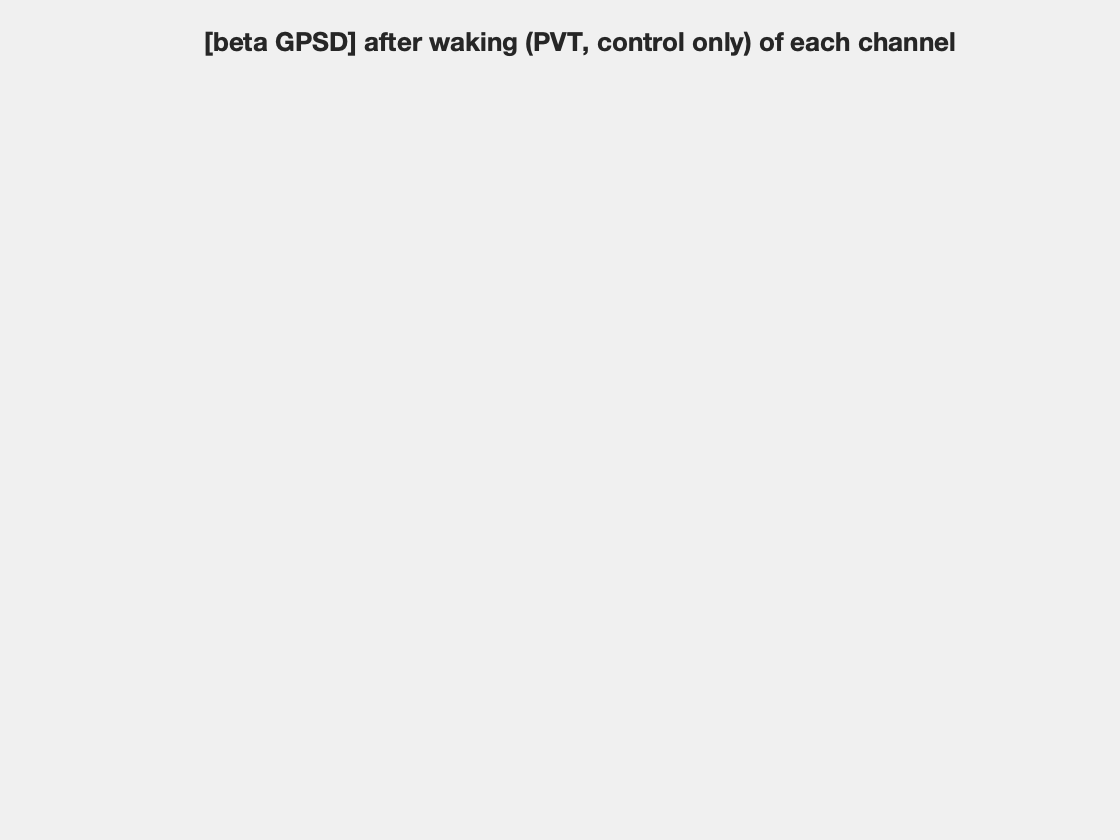

close all
figure('Visible','on')
T = tiledlayout(3,1);
T.Title.String = sprintf('[%s %s] after waking (%s, %s only) of each channel', bandname, upper(DV), cogtask,  condition2analyze);
T.Title.Interpreter = "none";
T.Title.FontWeight = "bold";

% FURTHER UNSTACK DATA
channames = cellstr(compose("ch%02d",1:23));
X_bsl = unstack(df(df.condition == 'baseline', {'chan','sbj',IV}),{IV},'chan','NewDataVariableNames',channames);
X_ctr = unstack(df(df.condition == 'control', {'chan','sbj',IV}),{IV},'chan','NewDataVariableNames',channames);
Y_bsl = unstack(df(df.condition == 'baseline', {'chan','sbj',DV}),{DV},'chan','NewDataVariableNames',channames);
Y_ctr = unstack(df(df.condition == 'control', {'chan','sbj',DV}),{DV},'chan','NewDataVariableNames',channames);
cx_bsl = unstack(df(df.condition == 'baseline', {'chan','sbj',IV_level}),{IV_level},'chan','NewDataVariableNames',channames);
cx_ctr = unstack(df(df.condition == 'control', {'chan','sbj',IV_level}),{IV_level},'chan','NewDataVariableNames',channames);
Y_bsl.sbj = [];
Y_ctr.sbj = [];
cx_bsl.sbj = [];
X_ctr.sbj = [];
cx_ctr.sbj = [];
X_bsl.sbj = [];
sortbyIV = true

sortbyIV = logical
   1


if sortbyIV
    [~,chsort] = sort(mean(X_bsl{:,:}),'descend');
    sort_str = sprintf('sorted by its %s during baseline',IV);
    
    X_bsl = X_bsl(:,chsort);
    X_ctr = X_ctr(:,chsort);
    Y_bsl = Y_bsl(:,chsort);
    Y_ctr = Y_ctr(:,chsort);
    cx_bsl = cx_bsl(:,chsort);
    cx_ctr = cx_ctr(:,chsort);

    df.chan = ordinal(df.chan, compose('%d', chsort)') ;
    df_bsl.chan = ordinal(df_bsl.chan, compose('%d', chsort)) ;
    df_ctr.chan = ordinal(df_ctr.chan, compose('%d', chsort)) ;
    df_lgt.chan = ordinal(df_lgt.chan, compose('%d', chsort)) ;

else
sort_str = '';
chsort = 1:23

end



% SUBJECT IDS
sbjid_list = unique(df.sbj);
numsubj = numel(sbjid_list);
example_subject = sbjid_list(1);


# CORREL LATION ANALAYSIS: PRETTY COOL RESULTS AND ANALYSIS


setxtickcat = @(ca) set(ca,"XTick",categorical(1:23),"XTickLabel",compose('%d',chsort))

setxtickcat = function_handle with value:
    @(ca)set(ca,"XTick",categorical(1:23),"XTickLabel",compose('%d',chsort))


setxtick = @(ca) set(ca,"XTick",(1:23),"XTickLabel",compose('%d',chsort))

setxtick = function_handle with value:
    @(ca)set(ca,"XTick",(1:23),"XTickLabel",compose('%d',chsort))



setsigstar = @(i,ylim,chname) text(i/23,.05,sprintf('*%s*',chname(3:4)),'Color','w','HorizontalAlignment','right','BackgroundColor','k','FontSize',8,'Units','normalized'); 


% EFFECT OF WAKING ON THE ***DV*** FOR EACH CHANNEL
    % PLOT
    nexttile(); hold on;
    boxchart(Y_bsl{:,:},'BoxFaceColor','k','BoxWidth',.5,'BoxLineColor','k','MarkerColor','k','WhiskerLineColor','k');
    boxchart(Y_ctr{:,:},'BoxFaceColor','r','BoxWidth',.3,'BoxLineColor','r','MarkerColor','r','WhiskerLineColor','r');           

    % TEST    
    for i=1:23
        chname = Y_bsl.Properties.VariableNames{i};
        p= ttest(Y_bsl{:,i}, Y_ctr{:,i});
        if p<=.05
            setsigstar(i,ylim,chname) 
        end
    end

p = 1

p = 0

p = 0

p = 1

p = 0

p = 1

p = 0

p = 0

p = 0

p = 1

p = 0

p = 0

p = 1

p = 1

p = 1

p = 1

p = 1

p = 0

p = 1

p = 1

p = 1

p = 1

p = 0

    ylabel(DV,'Interpreter','none')
    setxtickcat(gca)
    xlabel(sprintf('Channel (%s)',sort_str))
    ylabel(sprintf('%s %s @t=%d',bandname, upper(DV),t))
    legend('baseline','control')

%     nexttile(); text('average topoplots of DV baseline')
%     nexttile(); text('average topoplots of DV control')
% EFFECT OF WAKING ON THE ***IV*** FOR EACH CHANNEL   
    % PLOT
    nexttile();
    hold on;
    boxchart(X_bsl{:,:},'BoxFaceColor','k','BoxWidth',.5,'BoxLineColor','k','MarkerColor','k','WhiskerLineColor','k');
    boxchart(X_ctr{:,:},'BoxFaceColor','r','BoxWidth',.3,'BoxLineColor','r','MarkerColor','r','WhiskerLineColor','r');            

    % TEST
    for i=1:23
        chname = X_bsl.Properties.VariableNames{i};
        p= ttest(X_bsl{:,i}, X_ctr{:,i});
        if p<=.05
            setsigstar(i,ylim,chname) 
%             text( (i-1)/23,min(ylim),sprintf('*\n*%s*\n*',chname(3:4)),'Color','m','HorizontalAlignment','center','Units','normalized');
        end
    end

p = 0

p = 0

p = 0

p = 0

p = 0

p = 0

p = 0

p = 0

p = 1

p = 1

p = 0

p = 0

p = 0

p = 0

p = 0

p = 0

p = 0

p = 0

p = 0

p = 0

p = 0

p = 0

p = 0

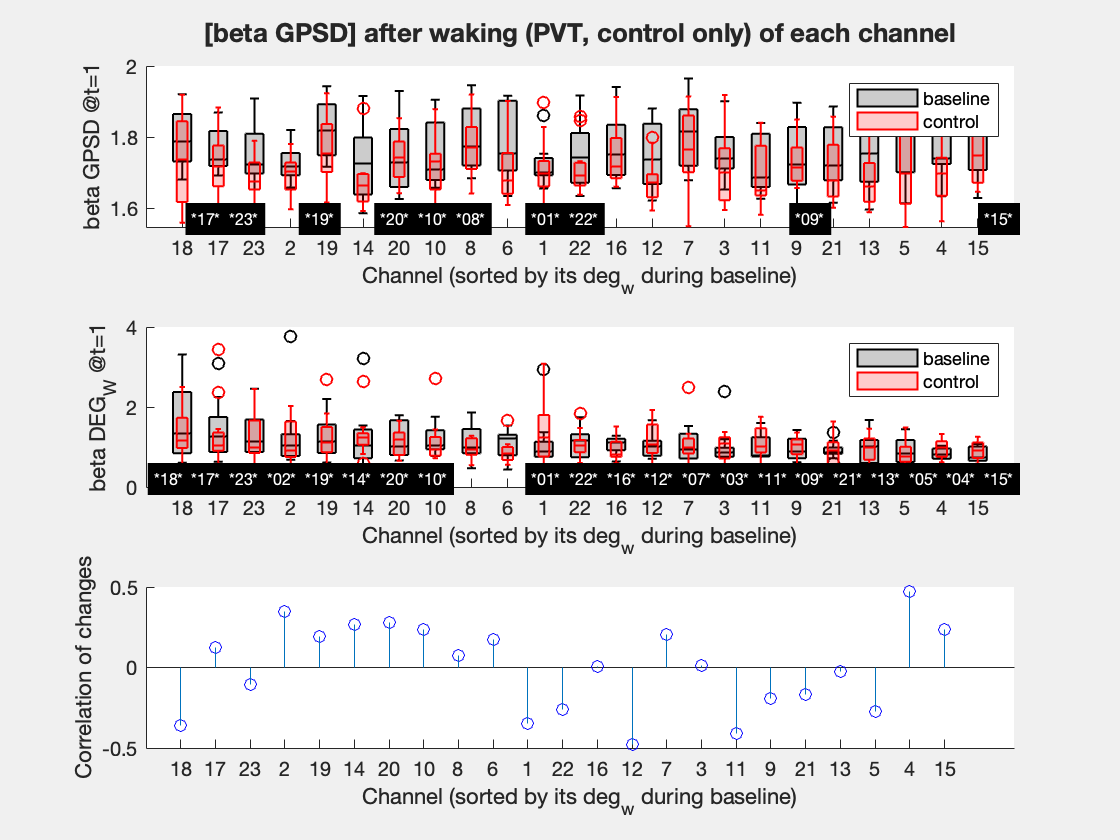

    ylabel(sprintf('%s %s @t=%d',bandname, upper(IV),t))
    setxtickcat(gca)
    xlabel(sprintf('Channel (%s)',sort_str))
    legend('baseline','control')

%     nexttile(); text('average topoplots of IV baseline')
%     nexttile(); text('average topoplots of IV control')
    
% COMPARING THE EFFECTS
    % TEST
% EFFECTS
    dX = X_bsl{:,:} - X_ctr{:,:};
    dY = Y_bsl{:,:} - Y_ctr{:,:};
    [R,P] = deal([]);
    for i=1:23
        [r, p] = corrcoef(dX(:,i), dY(:,1));
        R(i) = r(2); P(i) = p(2) ;
    end

    % PLOT
    nexttile();
    hold on;    
    stem(1:23, R,'MarkerEdgeColor','b');
    scatter(find(P<.05), R((P<.05)),'b','filled','MarkerFaceColor','y','MarkerEdgeColor','b','Marker','square','SizeData',400);        
    scatter(find(P<.05), R((P<.05)),'b','filled','MarkerFaceColor','c','MarkerEdgeColor','k','Marker','*','SizeData',400);    
    
    setxtick(gca)
    ylabel('Correlation of changes','Interpreter','none')    
    xlabel(sprintf('Channel (%s)',sort_str))


S = subjects(cogtask);

plotmytopo = @(X,chan) topoplot(X, S.chan,'style','map','maplimits','maxmin','emarker2',{chan,'*','m'});
run_plots_sbj = true;
for j = 1:numsubj
    
    sbj_id = sbjid_list(j);

    % RUN PLOTS
        if run_plots_sbj
            F_sbj= figure('GraphicsSmoothing','off','Visible','on');
            % PLOTS PLOTS
            % PLOT BASELINE STUFF
                % PLOT 1
                nexttile();   
                plotmytopo(Y_bsl{j,:},cx1_fs_ctr);
                topoplot(Y_bsl, S.chan,'style','map','maplimits','maxmin');
                title(sprintf('%s during BL',DV))
            
                % PLOT 
                nexttile();   
                plotmytopo(X_bsl{j,:},cx1_fs_ctr)
                title(sprintf('%s during BL',IV));
        
            % CONTROL
                % PLOT DV
                nexttile();   
                plotmytopo(Y_ctr{j,:},cx1_bsl{j,:})
                title(sprintf('%s during CTR',DV))
            
                % PLOT IV
                nexttile();   
                plotmytopo(X_ctr{j,:},cx1_bsl)
                title(sprintf('%s during CTR',IV))
        
            % DIFFERENCE TOPOPLOTS
                % PLOT DV
                nexttile();   
                plotmytopo(dY{j,:},same_cx1)                
                title(sprintf('Change in %s',DV))
            
                % PLOT IV
                nexttile();   
                plotmytopo(dX,same_cx1) 
                title(sprintf('Change in %s',IV))
            
            % EFFECTS
            % ON DV 
                nexttile(); hold on;
                scatter(1:23, Y_bsl{j,:},'filled','k'); 
                scatter(1:23, Y_ctr{j,:},'filled','r'); 
                stem(1:23,dY{j,:})
                legend({'BL','CTR','Change'},'FontSize',6)
                xlabel('channel')
                ylabel(DV)
            % ON IV
                nexttile(); hold on;
                scatter(1:23, X_bsl,'filled','k'); 
                scatter(1:23, X_ctr,'filled','r'); 
                stem(1:23,dX)
                legend({'BL','CTR','Change'},'FontSize',6)
                xlabel('channel')
                ylabel(IV)
        
            % SIMILARITY OF EFFECTS
            nexttile; hold on;
            scatter(dX, dY,'filled','green');
            [r,p] = corrcoef(dX, dY);
            text(0.05,.8,sprintf('r=%.02f p=%.02f',r(2),p(2)),'Units','normalized','FontSize',8);
            axis square
            
            xlabel(sprintf('Change in %s',IV));
            ylabel(sprintf('Change in %s',DV));
            line(xlim,ylim)
            figure; 
        end
end






SOME ANALSYS ON THE AGGREGATE DATA

close all;
F_sum = figure('GraphicsSmoothing','off','Visible','on');
fig_anz_idx = reshape(1:5*6,6,[])';

FT = tiledlayout(size(fig_anz_idx,1),size(fig_anz_idx,2));

df_tmp = dfrmcats(df(df.condition == condition2analyze | df.condition == "baseline",:));


df_summ = sortrows(groupsummary(df_tmp, {'condition','chan'},'mean',{DV,IV}),{'condition','chan'});
getvar = @(desired_var,desired_condition) df_summ.(desired_var)(df_summ.condition == desired_condition);


Y_bsl = getvar(DV_mean, 'baseline') ;
X_bsl = getvar(IV_mean, 'baseline') ;
[cx1_fs_bsl,cx1_ch_bsl] = groupcounts(df_bsl.chan(df_bsl.(IV_level) == numlevels));

X_ctr = getvar(IV_mean, 'control') ;
Y_ctr = getvar(DV_mean, 'control') ;
[cx1_fs_ctr,cx1_ch_ctr] = groupcounts(df_ctr.chan(df_ctr.(IV_level) == numlevels));


dY = Y_bsl -  Y_ctr; 
dX =X_bsl -  X_ctr; 



plotmytopo = @(X) topoplot(X, S.chan,'style','map','maplimits','maxmin');
plotmytopowchan = @(X,chan) topoplot(X, S.chan,'style','map','maplimits','maxmin','emarker2',{chan,'*','m'});

 % PLOTS PLOTS
% PLOT BASELINE STUFF
   
    cond_name = 'baseline';    
    % PLOT 1
    nexttile(fig_anz_idx(1,1));   
    plotmytopo(Y_bsl);
    title(sprintf('Mean %s during %s',DV, cond_name))

    % PLOT 
    nexttile(fig_anz_idx(1,2));  hold on;  
    plotmytopo(X_bsl);
    title(sprintf('Mean %s during %s',IV, cond_name))

    % HIST 
    nexttile(fig_anz_idx(1,3));   hold on;
    scatter(cx1_ch_bsl,cx1_fs_bsl,'black');
    
    ylabel(sprintf('# of times chan had\n HIGH %s during BL',IV),'Interpreter','none')

% CONTROL
    cond_name = 'control';
    % PLOT 1
    nexttile(fig_anz_idx(2,1)); hold on;   
    plotmytopowchan(Y_bsl,cx1_fs_ctr)  ;
    title(sprintf('Average %s during %s',DV, cond_name))

    % PLOT 
    nexttile(fig_anz_idx(2,2));   
    plotmytopowchan(X_bsl,cx1_fs_ctr)  ;
    title(sprintf('Average %s during %s',IV, cond_name))

    % HIST 
    nexttile(fig_anz_idx(2,3));   
    scatter(cx1_ch_ctr,cx1_fs_ctr,'black');
    ylabel(sprintf('# of times chan had\n HIGH %s during Control',IV),'Interpreter','none')
    

% DIFFERENCE TOPOPLOTS

    % PLOT DV
    nexttile(fig_anz_idx(3,1));   
    hold on;    
    topoplot(dY, S.chan,'style','map','maplimits','maxmin');
    title(sprintf('Change in %s',DV))

    % PLOT IV
    nexttile(fig_anz_idx(3,2));   
    hold on;     
    topoplot(dX, S.chan,'style','map','maplimits','maxmin');
    title(sprintf('Change in %s',IV))

% EFFECTS
% ON DV 
    nexttile(fig_anz_idx(4,1));
    hold on;
    scatter(1:23, Y_bsl,'k*'); 
    scatter(cx1_ch_bsl,Y_bsl(cx1_ch_bsl),'filled', 'k')   

    scatter(1:23, Y_ctr,'r*'); 
    scatter(cx1_ch_ctr,Y_ctr(cx1_ch_ctr),'filled', 'r')    
    
    stem(1:23,dY,'g')
    xlabel('channel')
    ylabel(DV)

% ON IV
    nexttile(fig_anz_idx(4,2)); hold on;

    scatter(1:23, X_bsl,'k*'); 
    scatter(cx1_ch_bsl,X_bsl(cx1_ch_bsl),'filled','k') 

    scatter(1:23, X_ctr,'r*'); 
    scatter(cx1_ch_ctr,X_ctr(cx1_ch_ctr),'filled','r')    
    
    stem(1:23,dX,'m')


    xlabel('channel');
    ylabel(IV)   ;

% SIMILARITY OF EFFECTS
    nexttile(fig_anz_idx(5,1),[1,2]); hold on;

scatter(dX, dY,'green','filled','SizeData',10,'MarkerFaceColor','y','Marker','square');
scatter(dX(cx1_ch_bsl), dY(cx1_ch_bsl),'MarkerEdgeColor','k','Marker','square');
scatter(dX(cx1_ch_ctr), dY(cx1_fs_ctr),'MarkerEdgeColor','r','Marker','o');


[r,p] = corrcoef(dX, dY);
text(0.05,.8,sprintf('r=%.02f p=%.02f',r(2),p(2)),'Units','normalized','FontSize',8);
axis square

xlabel(sprintf('Change in %s',IV));
ylabel(sprintf('Change in %s',DV));
line(xlim,ylim)

close all;
F= figure('GraphicsSmoothing','off','Visible','on');
numanz = 10;
numsubj = 3;
F_t = tiledlayout('flow');
close all force
IV_bsl = sprintf('%s_bsl',IV);
IV_ctr = sprintf('%s_ctr',IV);
IV_diff = sprintf('%s_diff',IV);
IV_diff_pval = strcat(IV_diff, '_pval');

IV_level_bsl = sprintf('%s_bsl',IV_level);
IV_level_ctr = sprintf('%s_ctr',IV_level);
IV_level_diff = sprintf('%s_diff',IV_level);

DV_bsl = sprintf('%s_bsl',DV);
DV_ctr = sprintf('%s_ctr',DV);
DV_diff = sprintf('%s_diff',DV);
DV_diff_pval = strcat(DV_diff, '_pval');


% F_sbj_plot_idx = reshape(1:numsubj*numanz,numsubj,numanz)';


IV_bsl = sprintf('%s_bsl',IV);
IV_ctr = sprintf('%s_ctr',IV);
IV_diff = sprintf('%s_diff',IV);
IV_diff_pval = strcat(IV_diff, '_pval');

IV_level_bsl = sprintf('%s_bsl',IV_level);
IV_level_ctr = sprintf('%s_ctr',IV_level);
IV_level_diff = sprintf('%s_diff',IV_level);

DV_bsl = sprintf('%s_bsl',DV);
DV_ctr = sprintf('%s_ctr',DV);
DV_diff = sprintf('%s_diff',DV);
DV_diff_pval = strcat(DV_diff, '_pval');

numanz = 5;
F_t = tiledlayout(numanz,numsubj);
F_sbj_plot_idx = reshape(1:numsubj*numanz,numsubj,numanz)';


for j = 1:3:10

    % get  data of channels with high IV DURING baseline
    rows_iv_high_at_bl = df_chan.(IV_level_bsl) == numlevels;
    df_sbj_iv_high_at_bl = df_chan(rows_iv_high_at_bl,:);
    
    % get  data of channels with high IV during control
    rows_iv_high_at_ctr = df_chan.(IV_level_ctr) == numlevels;
    df_sbj_iv_high_at_ctrl = df_chan(rows_iv_high_at_ctr,:);

    % get data of channels with high IV in both conditions
    rows_iv_high_at_both = rows_iv_high_at_bl&rows_iv_high_at_ctr;
    numchan_with_iv_high_at_both = sum(rows_iv_high_at_ctr);
    df_sbj_iv_high_at_both = df_chan(rows_iv_high_at_both,:);

    % PLOTS PLOTS PLOTS

    % PLOT 1
    nexttile(F_sbj_plot_idx(1,j));     
    topoplot(df_chan.(DV_bsl_mean), S.chan,'style','map','emarker2',{df_sbj_iv_high_at_bl.chan,'diamond','w'});
    title(sprintf('%s of nodes with high %s during BL', DV,IV))

    % PLOT 2
    nexttile(F_sbj_plot_idx(2,j));     
    topoplot(df_chan.(DV_ctr_mean), S.chan,'style','map','emarker2',{df_sbj_iv_high_at_ctrl.chan,'diamond','w'});
    title(sprintf('%s of nodes with high %s during BL', DV,IV))
    
    % PLOT 3
    nexttile(F_sbj_plot_idx(3,j));         
    topoplot(df_chan.mean_gpsd_diff, S.chan,'style','map','emarker2',{df_sbj_iv_high_at_both.chan,'diamond','w'});
    

%     % PLOT 3
    nexttile(F_sbj_plot_idx(4,j));        
    hold on;
    scatter(df_sbj_iv_high_at_both, DV_bsl_mean,DV_ctr_mean,'filled','ColorVariable','chan');
    xlabel(sprintf('%s nodes during BL',DV))
    ylabel(sprintf('%s nodes during CTRL',DV))

    

    if j == numsubj
        title(sprintf('%s of nodes with high %s in both conditions',DV,IV));    
        legend({sprintf('%s during BL', DV),sprintf('%s during CTRL', DV)})
    elseif j == numsubj+1


    end


    nexttile(F_sbj_plot_idx(5,j)); 
    histogram(df_sbj_iv_high_at_both.(DV_diff_mean))
    histogram(df_sbj_iv_high_at_both.(DV_diff_mean))    
    xlabel(sprintf('change in %s',DV))

    
    drawnow
end



## Next we need to get data for each channel


df_test = table;
df_chan = table();
for i = 1:23   
    for j = 1:numsubj
        df_init = table;
        df_init.chan = i;
        df_init.sbj = sbjid_list(j);

        % BASELINE 
        bsl_rows = df.condition == 'baseline' & df.chan == i & df.sbj == sbjid_list(j);                        
        df_init.(DV_bsl) = df.(DV)(bsl_rows);
        df_init.(IV_bsl) = df.(IV)(bsl_rows);
        df_init.(IV_level_bsl) = df.(IV_level)(bsl_rows);

        % CONTROL
        ctr_rows = df.condition == 'control' & df.chan == i & df.sbj == sbjid_list(j);        
        df_init.(DV_ctr) = df.(DV)(ctr_rows);
        df_init.(IV_ctr) = df.(IV)(ctr_rows);
        df_init.(IV_level_ctr) = df.(IV_level)(ctr_rows);

        df_chan = [df_chan; df_init];


    end

    % RUN TESTS
    c_i = df_chan.chan == i;

    df_init = table;    
    df_init.chan = i;   
    
    df_init.(DV_diff_pval) = signrank(df_chan.(DV_ctr)(c_i),df_chan.(DV_bsl)(c_i));  
    df_init.(IV_diff_pval)  = signrank(df_chan.(IV_ctr)(c_i),df_chan.(IV_bsl)(c_i));  

    df_test= [df_test; df_init];

end
df_test = table;
df_chan = table();

## PLOT AGGREGATE AVERAGE DIFFERENCES

% ________PLOTS__________% ________PLOTS__________
df_chan_mean = groupsummary(df_chan,{'chan'},{'mean'});

close all
F_anat_test = figure('GraphicsSmoothing','off');
F_t = tiledlayout(5,3);
F_t.Title.String = sprintf('Effect of waking on %s and %s ',DV,IV);  


% --- PLOTS OF THE DV DV DV DV


    %  BASELINE PLOTS OF THE DV

        % TOPOPLOTS BASELINE
        nexttile(1)
        topoplot(df_chan_mean.(DV_bsl_mean), S.chan,'style','map','electrodes','ptsnumbers')  ;
        title(sprintf('MEAN %s during BL (%s)',IV, DV_bsl_mean))

        % SCATTER PLOTS BASELINE
        ax = nexttile(4);
        hold on;
        stem(df_chan_mean.chan, df_chan_mean.(DV_bsl_mean));
        xlabel('channel')
        ylabel(DV_bsl_mean)
        

    %  CONTROL PLOTS OF THE DV
        % TOPO: 
        nexttile(2)
        topoplot(df_chan_mean.(DV_ctr_mean), S.chan,'style','map','electrodes','ptsnumbers') ;
        title(sprintf('MEAN %s during CTRL (%s)',IV, DV_ctr_mean));
        
        % SCATTER
        ax = nexttile(5);
        stem(df_chan_mean.chan, df_chan_mean.(DV_ctr_mean));
        xlabel('channel')
        ylabel(DV_ctr_mean)

 

    % CHANGE IN DV AFTER WAKING
        dv_sig_change = find(df_test.(DV_diff_pval)<=.05);

        % TOPO: 
        nexttile(3)
        topoplot(df_chan_mean.(DV_diff_mean), S.chan,'style','map','emarker2',{dv_sig_change,'*','r'},'electrodes','ptsnumbers')  ;
        title(sprintf('MEAN CHANGE in %s after waking (%s)',IV, DV_diff_mean));

        % SCATTER
        ax = nexttile(6);
        hold on;
        stem(df_chan_mean.chan, df_chan_mean.(DV_diff_mean));
        scatter(dv_sig_change,zeros(numel(dv_sig_change),1), 'r*')
        xlabel('channel')
        ylabel(DV_diff_mean)

        
 % --- PLOTS OF THE IV IV IV IV 

    %  BASELINE PLOTS OF THE IV

        % TOPOPLOTS BASELINE
        nexttile(10)
        topoplot(df_chan_mean.(IV_bsl_mean), S.chan,'style','map','electrodes','ptsnumbers')  ;
        title(sprintf('MEAN %s during BL (%s)',IV, IV_bsl_mean))

        % SCATTER 
        ax = nexttile(13);
        hold on;
        stem(df_chan_mean.chan, df_chan_mean.(IV_bsl_mean));
        xlabel('channel')
        ylabel(IV_bsl_mean)
        
    %  CONTROL PLOTS OF THE IV

        % TOPO: 
        nexttile(11)
        topoplot(df_chan_mean.(IV_ctr_mean), S.chan,'style','map','electrodes','ptsnumbers') ;
        title(sprintf('MEAN %s during CTRL (%s)',IV, IV_ctr_mean));
        
        % SCATTER
        ax = nexttile(14);
        stem(df_chan_mean.chan, df_chan_mean.(IV_ctr_mean));
        xlabel('channel')
        ylabel(IV_ctr_mean)

 

    % CHANGE IN IV AFTER WAKING
        IV_sig_change = find(df_test.(IV_diff_pval)<=.05);

        % TOPO: 
        nexttile(12)
        topoplot(df_chan_mean.(IV_diff_mean), S.chan,'style','map','emarker2',{IV_sig_change,'*','r'},'electrodes','ptsnumbers')  ;
        title(sprintf('MEAN CHANGE in %s after waking (%s)',IV, IV_diff_mean));

        % SCATTER
        ax = nexttile(15);
        hold on;
        stem(df_chan_mean.chan, df_chan_mean.(IV_diff_mean));
        scatter(IV_sig_change,zeros(numel(IV_sig_change),1), 'r*')
        xlabel('channel')
        ylabel(IV_diff_mean)

# ANOTHER CORREL LATION ANALAYSIS (STILL DIFFICULT TO INTERPRETM ==). MAY OR MAY NOT BE THE SAME AS THE DELTA ANALYSIS

close all force
F= figure('GraphicsSmoothing','off','Visible','on');

numanz = 10;
numsubj = 3;
F_t = tiledlayout('flow');

% F_sbj_plot_idx = reshape(1:numsubj*numanz,numsubj,numanz)';
F_sbj_plot_idx = reshape(1:numsubj*numanz,numanz,numsubj)'


IV_bsl = sprintf('%s_bsl',IV);
IV_ctr = sprintf('%s_ctr',IV);
IV_diff = sprintf('%s_diff',IV);
IV_diff_pval = strcat(IV_diff, '_pval');

IV_level_bsl = sprintf('%s_bsl',IV_level);
IV_level_ctr = sprintf('%s_ctr',IV_level);
IV_level_diff = sprintf('%s_diff',IV_level);

DV_bsl = sprintf('%s_bsl',DV);
DV_ctr = sprintf('%s_ctr',DV);
DV_diff = sprintf('%s_diff',DV);
DV_diff_pval = strcat(DV_diff, '_pval');

S = subjects(cogtask);


df_test = table;
df_chan = table();

sbj_chan = @(df_cond_sbj,IV_lev,desired_level) df_cond_sbj.chan(df_cond_sbj.(IV_lev)==numlevels) 
for j = 1:3
    df_init = table;
    df_init.chan = i;
    df_init.sbj = sbjid_list(j);

    % BASELINE 
    df_bsl_sbj = sortrows(df_bsl(df_bsl.sbj == sbjid_list(j),:),'chan');  
    bsl_highchan = sbj_chan(df_bsl_sbj,IV_level,numlevels);

    % CONTROL
    df_ctr_sbj = sortrows(df_ctr(df_ctr.sbj == sbjid_list(j),:),'chan');  
    ctr_highchan = sbj_chan(df_ctr_sbj,IV_level,numlevels);

%     df_chan = [df_chan; df_init];

    % RUN TESTS
%     c_i = df_chan.chan == i;
% 
%     df_init = table;    
%     df_init.chan = i;   
%     
%     df_init.(DV_diff_pval) = signrank(df_chan.(DV_ctr)(c_i),df_chan.(DV_bsl)(c_i));  
%     df_init.(IV_diff_pval)  = signrank(df_chan.(IV_ctr)(c_i),df_chan.(IV_bsl)(c_i));  
% 
%     df_test= [df_test; df_init];


    % PLOT 1
    nexttile();   
    topoplot(df_bsl_sbj.(IV_level).*df_bsl_sbj.(DV), S.chan,'style','map','emarker2',{ctr_highchan,'diamond','w'},'maplimits','maxmin');

    % PLOT 
    nexttile();     
    topoplot(df_ctr_sbj.(IV_level).*df_ctr_sbj.(DV), S.chan,'style','map','emarker2',{ctr_highchan,'diamond','w'},'maplimits','maxmin');


    % PLOT
    nexttile();     
    hold on;
    scatter(df_bsl_sbj,IV,DV,'filled','MarkerFaceColor','k')
    scatter(df_ctr_sbj,IV,DV,'filled','MarkerFaceColor','r');
    axis square

    

end

## LIKELYHOODS

clearvars -except df_long
clc;
cogtask = 'PVT';
bandname  = 'beta';
IV = 'deg_w'; 
DV = 'gpsd'; 
numlevels = 3;
t=1;
categwthn_condition = true;
categwthn_subject = true;


DV_mean =  sprintf('mean_%s',DV);
IV_level  = sprintf('%s_level',IV);
desired_vars = [{DV},{IV},experimentalvars()];

settings_str = sprintf('%s task | %s %s | when t = %d',cogtask, bandname, IV, t);
anzinfo_str = sprintf('Change in %s %s after waking for each "good" subject',bandname, IV);
title_str = sprintf('%s\n%s',anzinfo_str, settings_str);

% LOAD DATA
df     = dflong2wide(df_long, cogtask, {'baseline', 'control','light'}, bandname, t,'keepchannels',true);
df = df(:,desired_vars);

% CATEGORIZE NETWORK PROPERTIES. 
df= categcolumn(df,IV,numlevels,"condition",categwthn_condition,"subject",categwthn_subject);
df.(IV_level) = findgroups(df.(IV_level));


% PLOT
close all
figure('WindowStyle','docked')
tiledlayout(2,2)


ax_jointp = nexttile(1,[1,2]);
x = df_wake.("chan");
y = df_wake.(IV_level);

h = histogram2(x,y,'DisplayStyle','bar3','FaceColor','flat');
h.BinMethod = 'integers'; 
ax_jointp.YTick  = 1:numlevels;
ax_jointp.YTickLabel  =cellstr(num2str([1:numlevels]'));

xlabel('channel')
ylabel(IV_level)
set(gca, 'YDir','normal')
view(2)

title('Joint Frequency Distribution: P(chan=i & K=j)','Interpreter','none')
colorbar
axis equal
figure(gcf)
F = [h.Values];

% PLOT LIKELYHOOD;
ax_img = nexttile(3); 

L = F./repmat(sum(F),23,1);
imagesc(L');


dv_str = sprintf('P( Node | %s = 1...%d)',IV_level, numlevels);
ylabel(dv_str,'Interpreter','none')
title(sprintf('LIKELYHOOD: %s',dv_str),'Interpreter','none')
xlabel('channel')
ylabel(IV_level)

ax_img.YTick  = 1:numlevels;
ax_img.YTickLabel  =cellstr(num2str([1:numlevels]'));
colorbar
set(gca, 'YDir','normal')


% FACET
nexttile(4)
L = F./repmat(sum(F),23,1);
varnames = cellfun(@(x) sprintf('P(chan | %s = %d)',IV, x), num2cell(1:numlevels), 'UniformOutput',false);
rownames = cellfun(@(x) sprintf('channel %d',x), num2cell(1:23), 'UniformOutput',false);

Lt =  array2table(L,VariableNames=varnames,RowNames=rownames);
ax_p = stackedplot(Lt,Lt.Properties.VariableNames(end:-1:1));
xlabel('channel')

figure(gcf)

# PLOT FIT AND SCATTER OF EACH CONDITION HIGHLIGHING THE DV AT THE EXTREMES OF THE IV

nexttile
[lm,ax_bsl] =  anzcond_scatt(df_bsl, DV,IV,IV_level,'anzexample',example_subject);
nexttile;
[lm,ax_ctr] =  anzcond_scatt(df_ctr, DV,IV,IV_level,'anzexample',example_subject);

% OVERLAY FIT OF BOTH COND
ax = nexttile; 
ax_bl_2 = copyobj(ax_bsl(2),ax );
set(ax_bl_2,'Color','k','LineWidth',5)

ax_ctr_2 = copyobj(ax_ctr(2),ax );
set(ax_ctr_2,'Color','r','LineWidth',5)


legend({sprintf('Nodes with LOW %s during baseline',IV),sprintf('Nodes with High %s during baseline',IV)})
drawnow;

# FUNCTIONS

function [lm,ax_lm] =  anzcond_scatt(df_condition, DV,IV,IV_level,opts)
    arguments
        df_condition
        DV
        IV
        IV_level
        opts.anzexample = [];
    end    
    low_level_rows =  df_condition.(IV_level) == 1;
    hgh_level_rows =  df_condition.(IV_level) == max(df_condition.(IV_level));
    mid_level_rows = ~low_level_rows & ~hgh_level_rows;
    
    % fit model
    lm = fitlm(df_condition,"linear","ResponseVar",(DV),"PredictorVars",(IV));
        
    % Plot 
    
    % PLOT LINEAR MODEL
    ax_lm = lm.plot;
    hold on;
    delete(ax_lm([1 3 4]))
    set(ax_lm(2),'LineStyle', '-','Color','k')
    
    % SCATTER PLOT FOR HIGH AND LOW LVELS
    scatter(df_condition(mid_level_rows,:),IV,DV,'MarkerEdgeColor',[.3 .3 .3],'SizeData',10);
    scatter(df_condition(low_level_rows,:),IV,DV,'filled','MarkerFaceColor','b','MarkerEdgeColor','none','SizeData',10);
    scatter(df_condition(hgh_level_rows,:),IV,DV,'filled','MarkerFaceColor','m','MarkerEdgeColor','none','SizeData',10);

    
    % SAME FOR 
    if ~isempty(opts.anzexample)
        eg_sbj_rows=  df_condition.sbj == opts.anzexample;

        
        lm_egsbj = fitlm(df_condition(eg_sbj_rows,:),"linear","ResponseVar",(DV),"PredictorVars",(IV));
        ax_lm_egsbj = lm_egsbj.plot;
        delete(ax_lm_egsbj([1 3 4]))
        set(ax_lm_egsbj(2),'LineStyle', '-','Color','w') 

        scatter(df_condition(low_level_rows & eg_sbj_rows,:),IV,DV,'MarkerFaceColor','b','MarkerEdgeColor','w','Marker','diamond','SizeData',100);    
        scatter(df_condition(hgh_level_rows & eg_sbj_rows,:),IV,DV,'MarkerFaceColor','m','MarkerEdgeColor','w','Marker','diamond','SizeData',100);
    end
end

function fixsigstar(h,p,bonfcorrect)

    if p<.05/(bonfcorrect)
            set(h(2),'String','*SIG!*')
            set(h(2),'Color','g',"FontSize",12)    
        else
            set(h(2),'String','n.s.')
            set(h(2),'Color','r',"FontSize",8)    
            set(h(1),'LineStyle',':','Color',[.3 .3 .3])        
    end
end